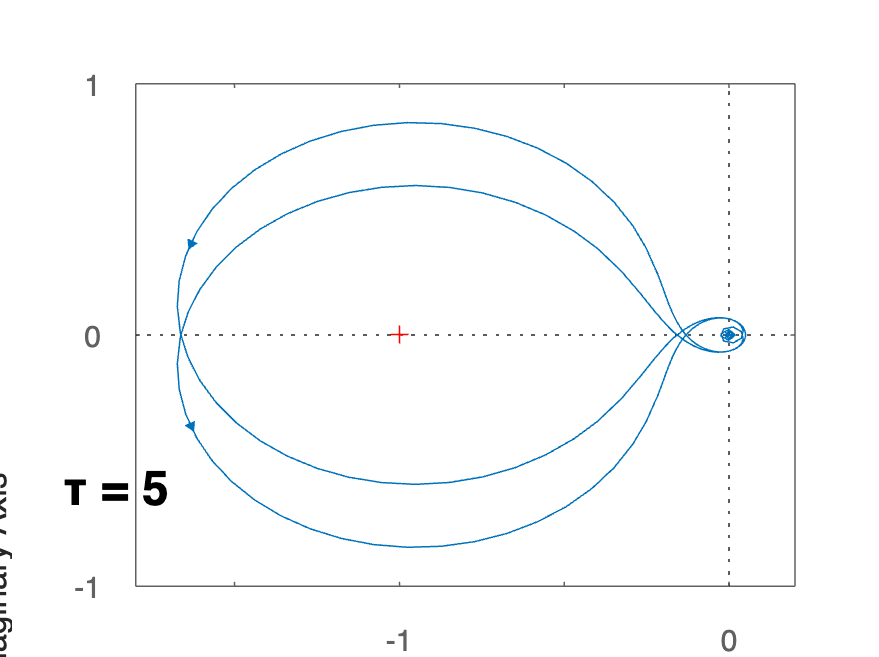

% % Годограф для запаздывания 0
% % sys_open = tf([9 3], [1 3 5],'InputDelay', 0);
% sys_open = tf([10 -6 1], [10 -1 38 20],'InputDelay', 0);
% nyquistplot(sys_open);
% title('τ = 0','FontSize', 16);
% % Годограф для запаздывания 0.5
% sys_open = tf([10 -6 1], [10 -1 38 20],'InputDelay', 0.5);
% nyquistplot(sys_open);
% title('τ = 0.5','FontSize', 16);
% 
% % Годограф для запаздывания 0.1
% sys_open = tf([10 -6 1], [10 -1 38 20],'InputDelay', 0.1);
% nyquistplot(sys_open);
% title('τ = 0.1','FontSize', 16);
% % Годограф для запаздывания 1
% sys_open = tf([10 -6 1], [10 -1 38 20],'InputDelay', 1);
% nyquistplot(sys_open)
% title('τ = 1','FontSize', 16);
% % Годограф для запаздывания 2
% sys_open = tf([10 -6 1], [10 -1 38 20],'InputDelay', 2);
% nyquistplot(sys_open);
% title('τ = 2','FontSize', 16);
% % Годограф для запаздывания 5
sys_open = tf([9 3], [1 3 5],'InputDelay', 0.2071);
nyquistplot(sys_open);
title('τ = 0.2071','FontSize', 16);

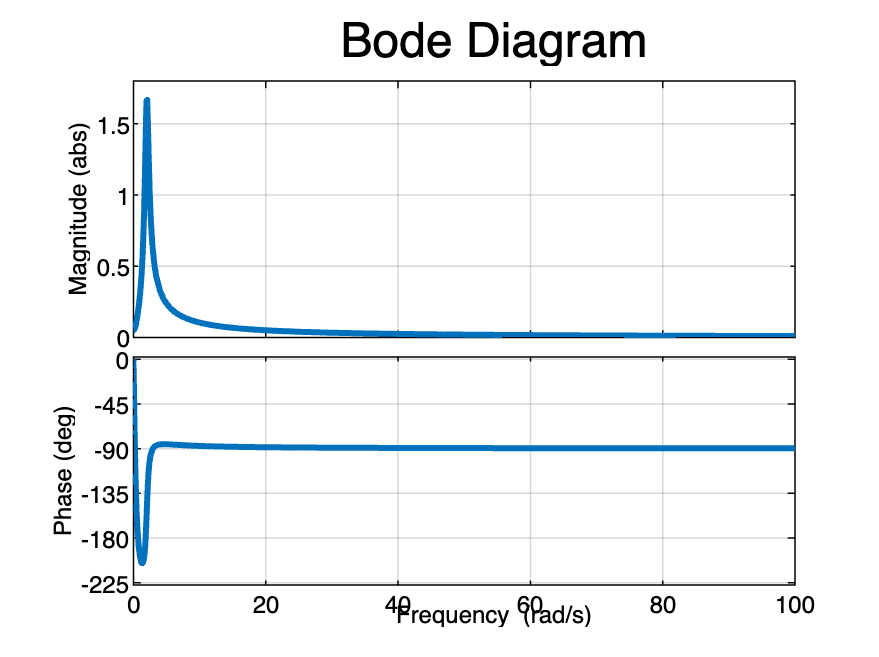


% строим АФХ и ФЧХ разомкнутой системы
sys_open = tf([10 -6 1], [10 -1 38 20]);
% sys_open = tf([9 3], [1 3 5]);
opt1 = bodeoptions;
opt1.FreqScale = 'linear';
opt1.MagScale = 'linear';
opt1.MagUnits = 'abs';
opt1.PhaseUnits = 'deg';
opt1.Title.FontSize = 16;
bodeplot(sys_open, opt1)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;


S = allmargin(sys_open)

S = struct with fields:
     GainMargin: [5.5522 0.7144]
    GMFrequency: [0.6846 1.8361]
    PhaseMargin: [-16.4741 78.8107]
    PMFrequency: [1.6642 2.4615]
    DelayMargin: [3.6026 0.5588]
    DMFrequency: [1.6642 2.4615]
         Stable: 1
